A.Date.Format = "dd/MM/uuuu HH:mm:ss";
A.Time.Format = "dd/MM/uuuu HH:mm:ss";

A.DateDef = A.Date + timeofday(A.Time);

A.Date = [];
A.Time = [];

A.JulianDate = exceltime(A.DateDef);

A.YearFraction = 2019+(A.JulianDate-43466)./365.25;

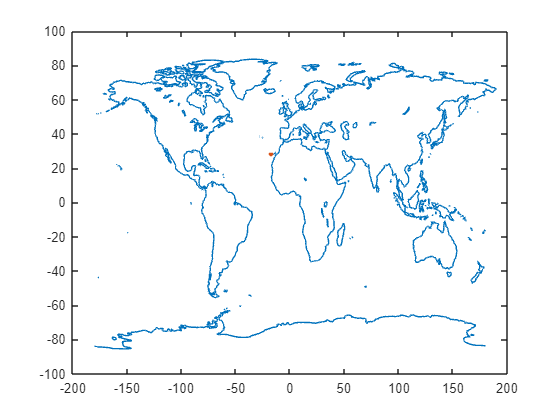

% load coastlines.mat
% plot(coastlon, coastlat)
% hold on
% plot(A.longitude, A.latitude, ".")
% hold off

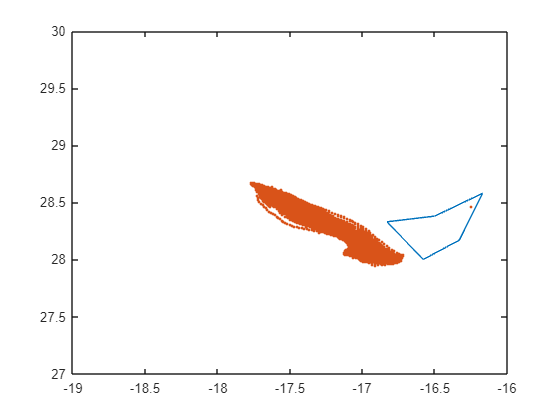

% xlim([-19 -16])
% ylim([27 30])

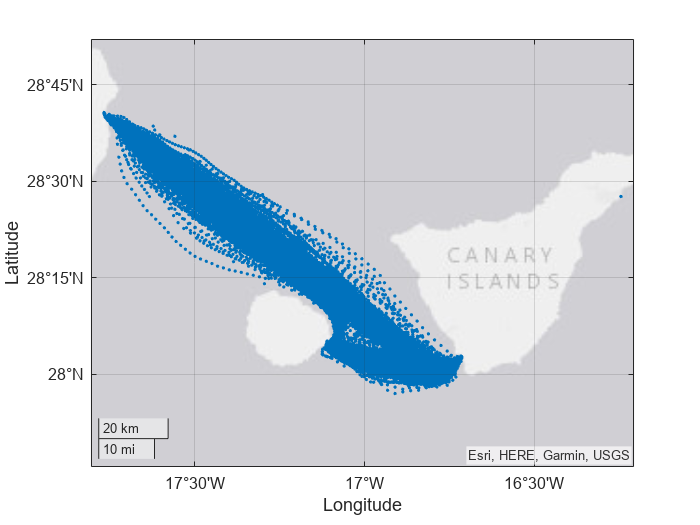

geoplot(A.latitude, A.longitude, ".")

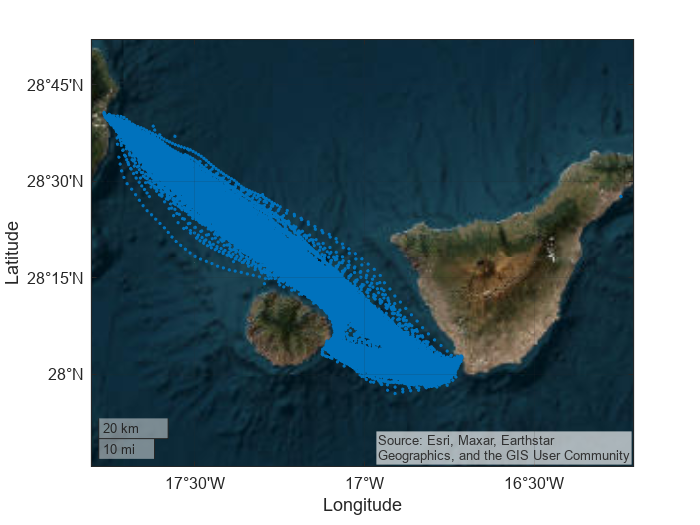

geobasemap satellite

noPorts = A(A.longitude > -17.74 & A.longitude < -16.73, :);
% -17.09 % Gomera

noPorts(noPorts.longitude < -17.09 & noPorts.latitude < 28.098, :) = [];

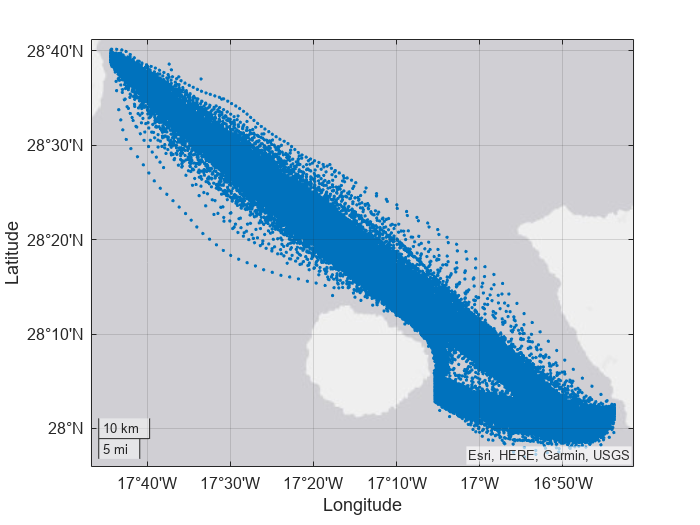

geoplot(noPorts.latitude, noPorts.longitude, ".")

noPorts2 = noPorts(noPorts.Type == "EQU", :);


% same = find(noPorts.latitude(:) == brushedCristianos(:,2));
% cristData = table(brushedCristianos(:,1), brushedCristianos(:,2), 'VariableNames' ,["longitude", "latitude"]);
% [cristianos, iPorts, icrist] = innerjoin(noPorts, cristData);

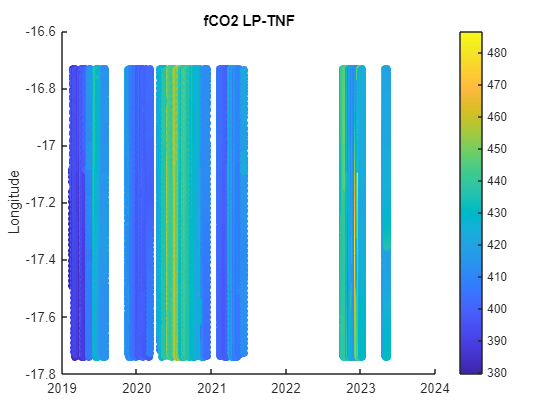

scatter(noPorts3.YearFraction, noPorts3.longitude, [], noPorts3.fCO2OKprevio, "filled")
colorbar;
title("fCO2 LP-TNF")
ylabel("Longitude")

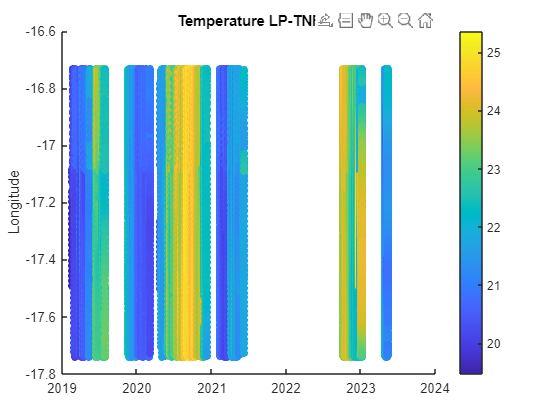

scatter(noPorts3.YearFraction, noPorts3.longitude, [], noPorts3.intaketemp, "filled")
colorbar;
title("Temperature LP-TNF")
ylabel("Longitude")

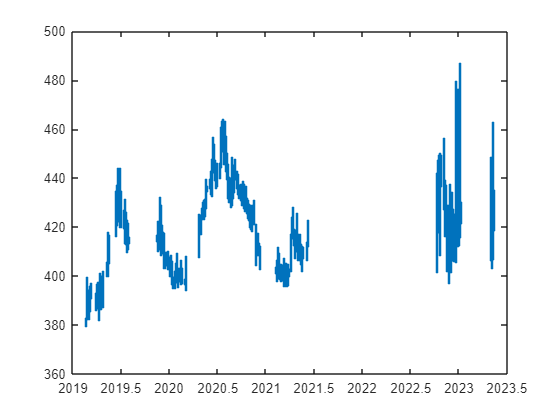

plot(noPorts3.YearFraction, noPorts3.fCO2OKprevio, ".")

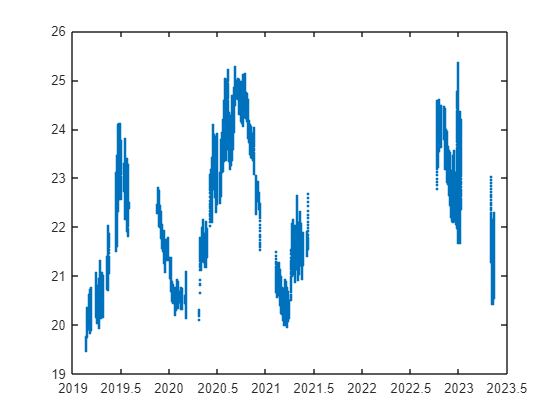

plot(noPorts3.YearFraction, noPorts3.intaketemp, ".")

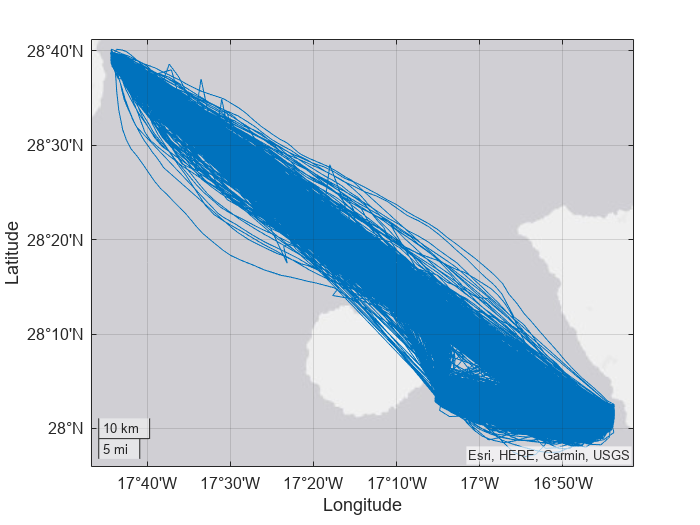

geoplot(noPorts3.latitude, noPorts3.longitude)

% punto TNF y LP -17.35-17.25 28.30 y 28.40
locTP= noPorts3(noPorts3.longitude > -17.35 & noPorts3.longitude < -17.25 & noPorts3.latitude > 28.3 & noPorts3.latitude < 28.4, :); 

% punto LG y TNF -16.91 y -16.81 27.99 y 28.09
locTG= noPorts3(noPorts3.longitude > -16.91 & noPorts3.longitude < -16.81 & noPorts3.latitude > 27.99 & noPorts3.latitude < 28.09, :);

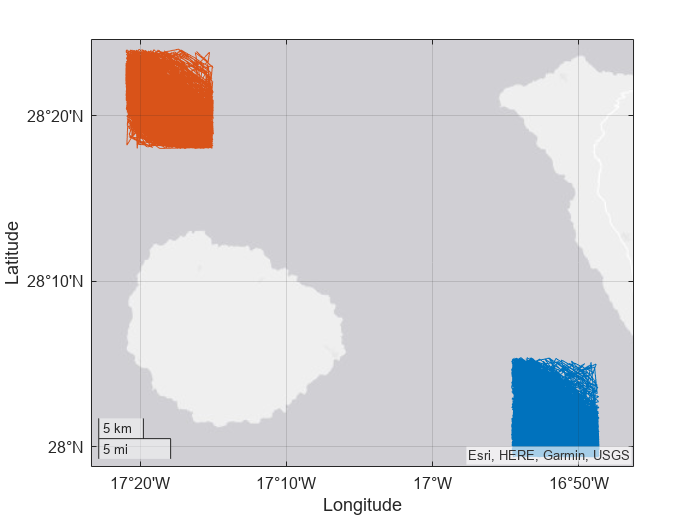

geoplot(locTG.latitude, locTG.longitude)
hold on
geoplot(locTP.latitude, locTP.longitude)
hold off

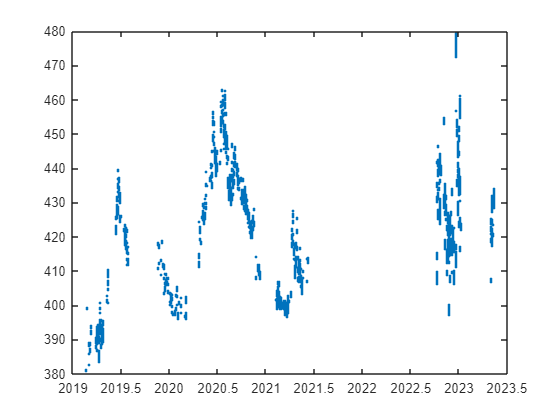

plot(locTP.YearFraction, locTP.fCO2OKprevio, ".")

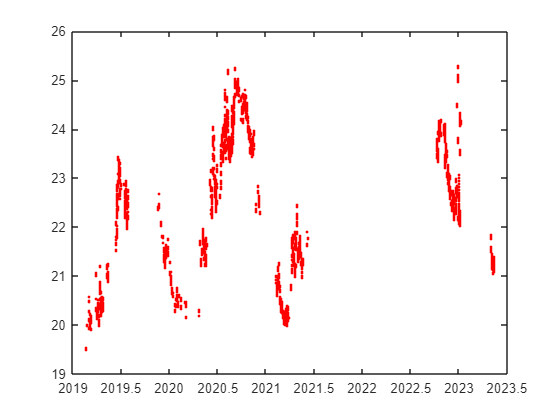

plot(locTP.YearFraction, locTP.intaketemp, "r.")

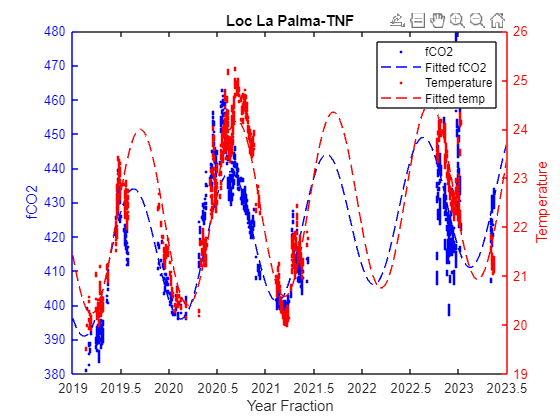

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
title("Loc La Palma-TNF")
plot(locTP.YearFraction, locTP.fCO2OKprevio, "b.")
hold on 
plot(fittedCO2tp, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
title("Loc La Palma-TNF")
plot(locTP.YearFraction, locTP.intaketemp, "r.")
hold on 
plot(fittedTemptp, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

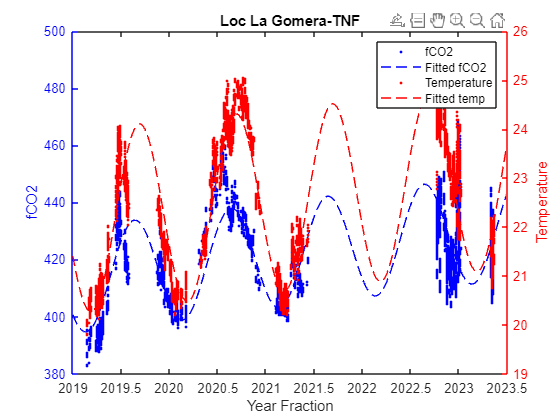

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
title("Loc La Gomera-TNF")
plot(locTG.YearFraction, locTG.fCO2OKprevio, "b.")
hold on 
plot(fittedCO2, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
title("Loc La Gomera-TNF")
plot(locTG.YearFraction, locTG.intaketemp, "r.")
hold on 
plot(fittedTemp, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

reducedTable = noPorts3(:, ["YearFraction", "fCO2OKprevio", "intaketemp", "longitude", "latitude"]);

reducedTLCO2 = TLCO2(:, ["JulianDate", "fCO2sw", "longitude", "latitude"]);

reducedTLtemp = TLcleanTemp(:, ["JulianDate", "IntakeTemp", "longitude", "latitude"]);

reducedTLtemp = 23756×4 table
    JulianDate    IntakeTemp    longitude    latitude
    __________    __________    _________    ________

      43503         18.747       -16.032        28.4 
      43503         18.746       -16.038      28.402 
      43503         18.745       -16.044      28.403 
      43503         18.745       -16.051      28.405 
      43503         18.744       -16.057      28.407 
      43503         18.743       -16.063      28.409 
      43503         18.743       -16.069      28.411 
      43503         18.742       -16.075      28.412 
      43503         18.741       -16.081      28.414 
      43503         18.741       -16.087      28.416 
      43503          18.74       -16.093      28.418 
      43503          18.74       -16.099       28.42 
      43503         18.739       -16.105      28.422 
      43503         18.

reducedTLtemp.fCO2sw = reducedTLCO2.fCO2sw;

reducedTLtemp.YearFraction = 2019+(reducedTLtemp.JulianDate-43466)./365.25;

reducedTLtemp.JulianDate = [];

reducedTLtemp = movevars(reducedTLtemp, "YearFraction", "Before","IntakeTemp");
reducedTLtemp = movevars(reducedTLtemp, "fCO2sw", "After", "YearFraction");

reducedTable = renamevars(reducedTable, ["intaketemp", "fCO2OKprevio"], ["IntakeTemp", "fCO2sw"]);

B = RenatePlot;
TLrows = B(B.longitude > -16.20 & B.longitude < -12, :);
TLrows.YearFraction = 2019+(TLrows.JulianDate-43466)./365.25;
TLrows.JulianDate = [];
allTable = vertcat(TLrows, reducedTable);


allTable = sortrows(allTable);

allTable.latitude(allTable.latitude > 29.5) = NaN;

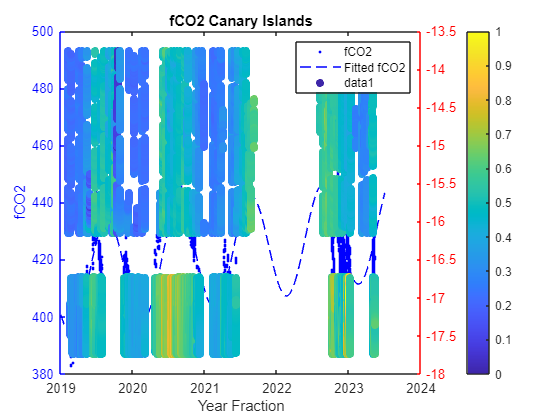

scatter(allTable.YearFraction, allTable.longitude, [], allTable.fCO2sw, "filled")
colorbar;
title("fCO2 Canary Islands")
ylabel("Longitude")
scatter(allTable.YearFraction, allTable.longitude, [], allTable.IntakeTemp, "filled")

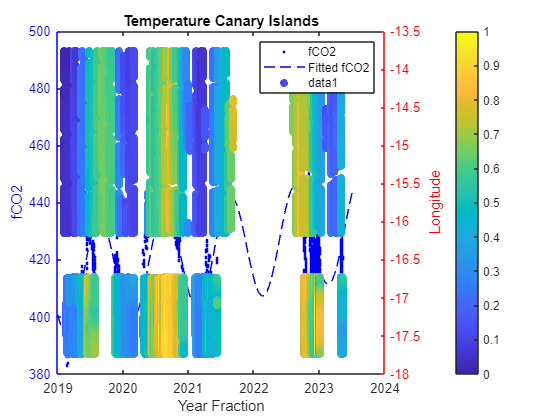

colorbar;
title("Temperature Canary Islands")
ylabel("Longitude")